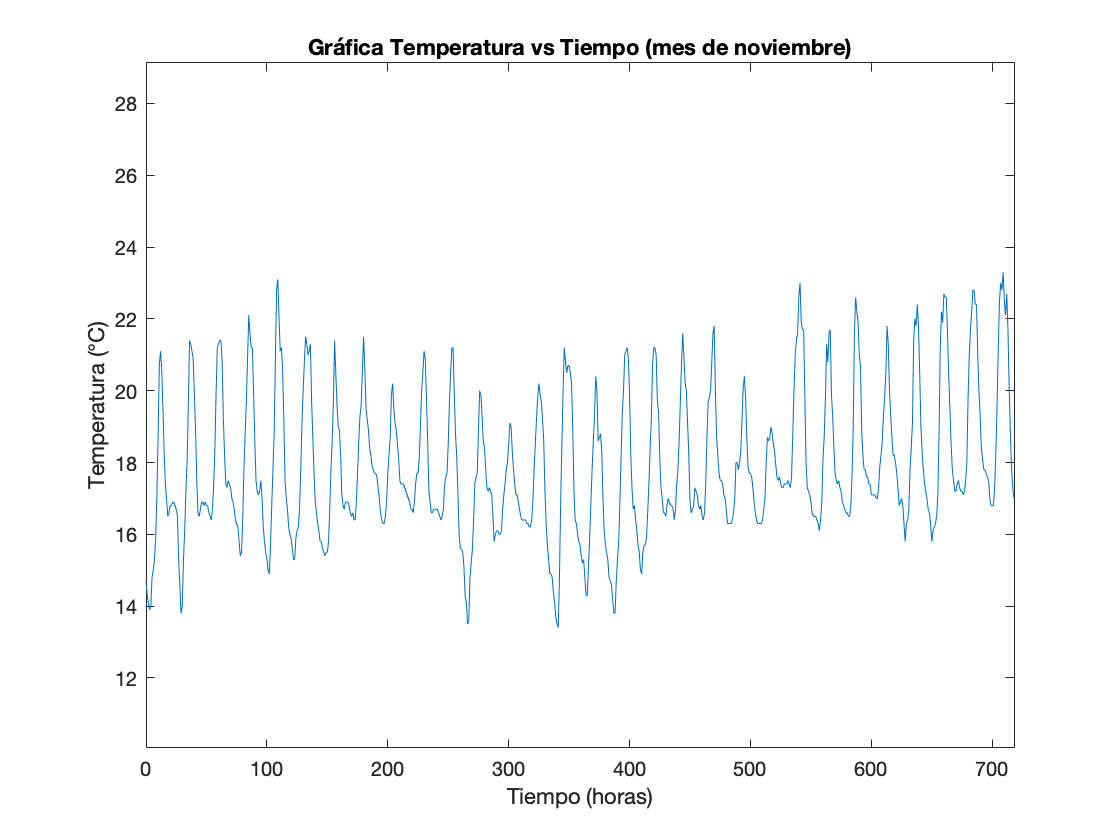

T = CargarData('data.csv');
t = (0:1:length(T)-1);

GraficaGeneral(T, t); hold off;

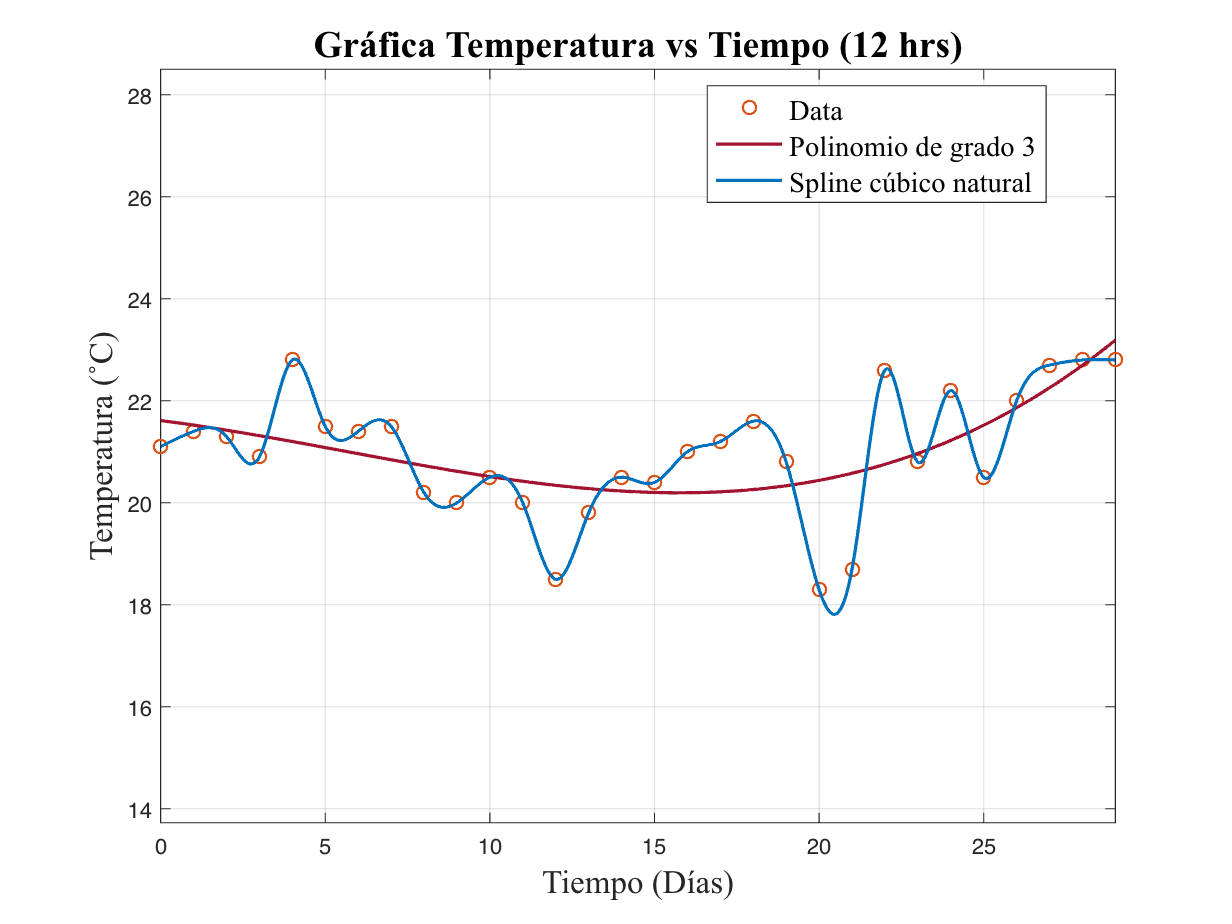

opcion = input('¿Usted tiene conocimiento del proyecto? Sí/No: ', 's');

if strcmp(opcion, 'Sí')
    hora = input("Ingresa la hora del día a analizar (0-23): ");
    grado = input("Ingresa el grado del polinomio aproximante: ");
else
    hora = 12; % Se define por defecto el mediodía
    grado = 3; % Se define por defecto un polinomio de mínimos cuadrados de grado 3
end

[T1, T2] = Grafica(T, hora+1, grado); hold off

disp(T1);

    i     x      y      h[i]    f[x(i),x(i+1)]    S"(x[i]) 
    __    __    ____    ____    ______________    _________

     0     0    21.1      1           0.3                 0
     1     1    21.4      1          -0.1          -0.14086
     2     2    21.3      1          -0.4           -1.8366
     3     3    20.9      1           1.9            5.6871
     4     4    22.8      1          -1.3           -7.1118
     5     5    21.5      1          -0.1              3.56
     6     6    21.4      1           0.1          0.071699
     7     7    21.5      1          -1.3           -2.6468
     8     8    20.2      1          -0.2            2.1156
     9     9      20      1           0.5           0.78458
    10    10    20.5      1          -0.5           -1.0539
    11    11   

disp(T2);

    i     (x-x[i])        a             b            c         d       [x(i), x(i+1)]  
    __    ________    __________    _________    _________    ____    _________________

     0    "(x-0)"      -0.023477            0      0.32348    21.1    "si x ∈ [0, 1]"  
     1    "(x-1)"       -0.28262    -0.070431      0.25305    21.4    "si x ∈ [1, 2]"  
     2    "(x-2)"         1.2539     -0.91828     -0.73566    21.3    "si x ∈ [2, 3]"  
     3    "(x-3)"        -2.1331       2.8435       1.1896    20.9    "si x ∈ [3, 4]"  
     4    "(x-4)"         1.7786      -3.5559      0.47726    22.8    "si x ∈ [4, 5]"  
     5    "(x-5)"       -0.58139         1.78      -1.2986    21.5    "si x ∈ [5, 6]"  
     6    "(x-6)"       -0.45309     0.035849      0.5172

function [T1, T2] = Grafica(T, hora, grado)
    
    T = T(hora:24:end);
    t = (0:1:length(T)-1);
    
    P = polyfit(t, T, grado);
    tt = linspace(0, length(t)-1, 1000);
    Pt = polyval(P, tt);
    
    % Gráfica de la data
    plot(t, T, 'o', "Color", '#D95319', "LineWidth", 1)
    grid on, hold on
    
    % Gráfica del polinomio de mínimos cuadrados
    plot(tt, Pt, "Color", '#A2142F', "LineWidth", 1.5)
    
    % Gráfica del Spline Cúbico Natural
    [T1, T2] = SplineCubicoNatural(t, T, '#0072BD');
    
    xlim([min(t)     max(t)    ])
    ylim([3/4*min(T) 5/4*max(T)])
    hold off
    
    legend(...
        "Data", ...
        "Polinomio de grado " + int2str(grado), ...
        "Spline cúbico natural", ...
        "Location", "best", ...
        "FontSize", 13, ...
        "FontName", "Times New Roman")
    
    xlabel(...
        "Tiempo (Días)", ...
        "FontSize", 15, "FontName", "Times New Roman")
    
    ylabel(...
        "Temperatura (˚C)", ...
        "FontSize", 15, "FontName", "Times New Roman" )
    
    title(...
        "Gráfica Temperatura vs Tiempo (" + int2str(hora-1) + " hrs)", ...
        "FontSize", 17, "FontName", "Times New Roman")
    
end